# Filtr Hilberta, demodulacja AM

Dane wstepne

A1=1; A2=2; A3=3; f1=1; f2=2; f3=3;
fs=1e3; fc=200; tvec=0:1/fs:1-fs; 
m = @(t) 1+A1*cos(2*pi*f1*t)+A2*cos(2*pi*f2*t)+A3*cos(2*pi*f3*t);


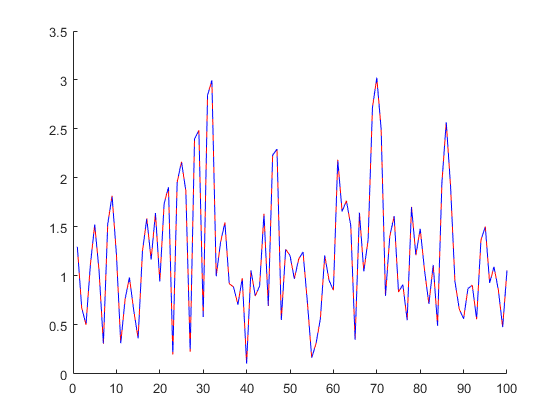

% compare hilbert and myhilbert
n = 100;
test = randn(n,1);

figure
hold on
plot(abs(myHilbert(test)), 'r')
plot(abs(hilbert(test)),'b--')
xlim([0 n])

function y = myHilbert(x)
    n = length(x);

    X = fft(x);
    complexX = 1i*X;
    
    posX = 2:floor(n/2)+mod(n,2);
    negX = ceil(n/2)+1+~mod(n,2):n;
    
    X(posX) = X(posX) + -1i*complexX(posX);
    X(negX) = X(negX) +  1i*complexX(negX);

    y = ifft(X);
end